clc
clear

加载训练后的深度学习网络

load Result001_2\002_resnet50_2023-12-08-16-07.mat
net_001_categorization=net;
load Result002\003_DeepLabv3+_resnet50_2023-11-27-19-09.mat
net_002_sand_smallrock=net;

load Result002_2\001_DeepLabv3+_resnet50_2023-12-01-17-37.mat
net_002_sand_mediumrock=net;

load Result002_3\001_DeepLabv3+_resnet50_2023-12-05-15-05.mat
net_002_sand_largerock=net;

load Result002_4\001_DeepLabv3+_resnet50_2023-12-07-20-41.mat
net_002_sand_hugerock=net;

加载所有的导航相机原始图像为一个数据集，图像是2048*2048

imds1=imageDatastore("002\","IncludeSubfolders",true)

imds1 =   ImageDatastore - 属性:

                       Files: {
                              ' ...Ro_GRAS_NaTeCamA-F-001_SCI_N_20210605105115_20210605105115_00022_A.png';
                              ' ...Ro_GRAS_NaTeCamA-F-001_SCI_N_20210606113032_20210606113032_00023_A.png';
                              ' ...Ro_GRAS_NaTeCamA-F-001_SCI_N_20210607121458_20210607121458_00024_A.png'
                               ... and 1306 more
                              }
                     Folders: {
                              'G:\2023.4Zr_data_processing\002'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


读取一张图像然后分割为512*512大小

i=1

i = 1

originImage=imread(imds1.Files{i});
subImages=cell(4,4)

subImages = 4×4 cell 数组
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


% 分割图像
for row = 1:4
    for col = 1:4
        % 计算当前子图像的索引
        rStart = (row-1)*512 + 1;
        rEnd = row*512;
        cStart = (col-1)*512 + 1;
        cEnd = col*512;
        % 提取子图像
        subImages{row, col} = originImage(rStart:rEnd, cStart:cEnd, :);
        subImage = originImage(rStart:rEnd, cStart:cEnd, :);
        % 对子图像执行第一步分类预测
        subImage_re=imresize(subImage,[224 224]);%改图像大小，符合分类网络的输入
        [im_pred,im_scores] = classify(net_001_categorization,subImage_re);%对图片进行分类，得到分类和每一类权重
        %分类后执行语义分割
        if im_pred=="Sand"
            cmap=[0 1 0];
            C1=ones(512,512);
            BW=labeloverlay(subImage,C1,"Colormap",cmap,"Transparency",0.6);
            subImages{row,col} = BW;
        elseif im_pred=="Sand with Small Rock"
            cmap=[0 0.8 0;0 0.45 0.07];
            C1=semanticseg(subImage,net_002_sand_smallrock);
            BW=labeloverlay(subImage,C1,"Colormap",cmap,"Transparency",0.6);
            subImages{row,col} = BW;
        elseif im_pred=="Sand with Medium Rock"
            cmap=[0 0.6 0;1 1 0.07];
            C1=semanticseg(subImage,net_002_sand_mediumrock);
            BW=labeloverlay(subImage,C1,"Colormap",cmap,"Transparency",0.6);
            subImages{row,col} = BW;
        elseif im_pred=="Sand with Large Rock"
            cmap=[0 0.4 0;0.85 0.33 0.10];
            C1=semanticseg(subImage,net_002_sand_largerock);
            BW=labeloverlay(subImage,C1,"Colormap",cmap,"Transparency",0.6);
            subImages{row,col} = BW;
        elseif im_pred=="Sand with Huge Rock"
            cmap=[0 0.3 0;1 0 0];
            C1=semanticseg(subImage,net_002_sand_hugerock);
            BW=labeloverlay(subImage,C1,"Colormap",cmap,"Transparency",0.6);
            subImages{row,col} = BW;
        elseif im_pred=="Rover and Rut"
            subImages{row,col} = subImage;
        elseif im_pred=="Sky"
            subImages{row,col} = subImage; 
        end
    end
end

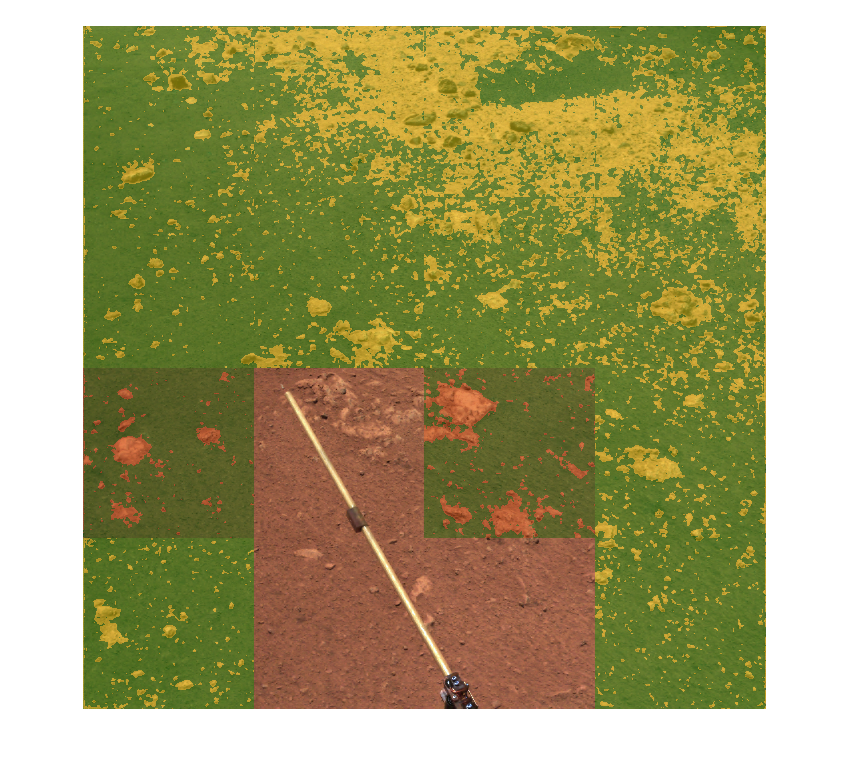

% 重新拼合图像
reassembledImage = cell2mat(subImages);

% 显示重新拼合的图像
imshow(reassembledImage);